Possible Fixed Points:


$$Fpts = \left(\begin{array}{c} \frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}\\ \frac{r}{2}+\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2} \end{array}\right)$$

Maximum number of possible Fixed Points:2


Zona 1: -10.00 <= r <= -2.00, el número de puntos fijos es 2
Zona 2: -2.00 <= r <= -2.00, el número de puntos fijos es 1
Zona 3: -2.00 <= r <= 2.00, el número de puntos fijos es 0
Zona 4: 2.00 <= r <= 2.00, el número de puntos fijos es 1
Zona 5: 2.00 <= r <= 10.00, el número de puntos fijos es 2
Valores de r representativos para cada zona:
    -6
    -2
     0
     2
     6

Puntos de bifurcación:
    -2     2



Zona 1: r = -6.00

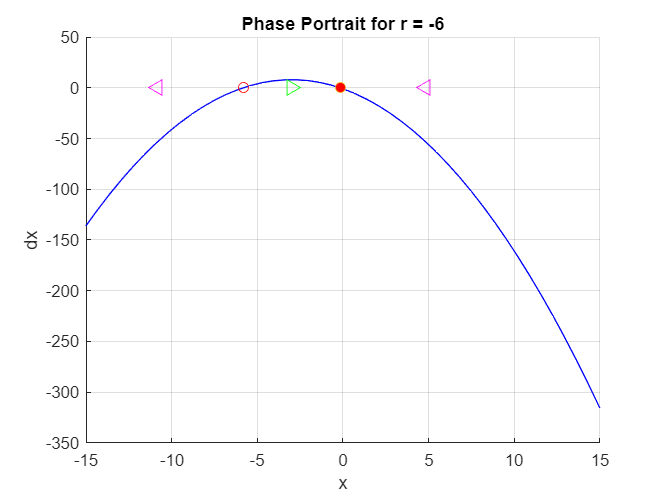

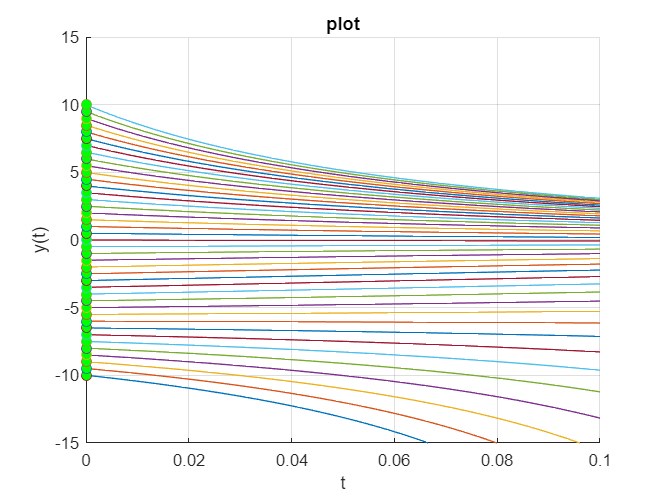

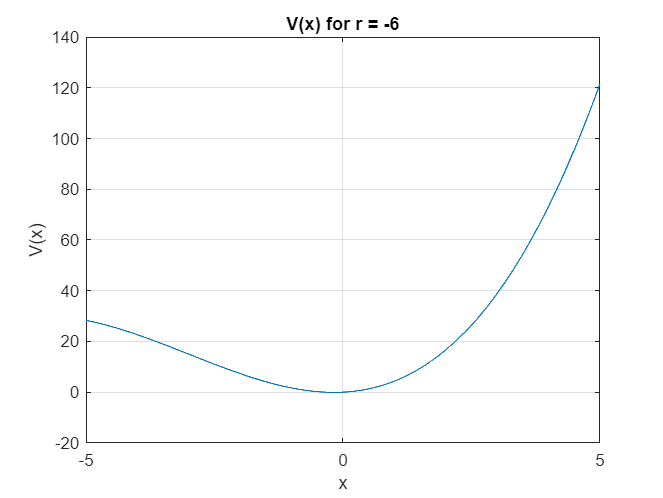

Zona 2: r = -2.00

There is a mixed Fixed Point at x = -2

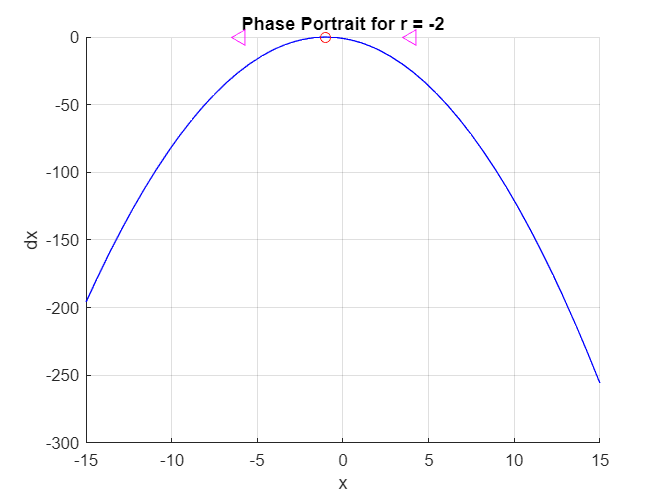

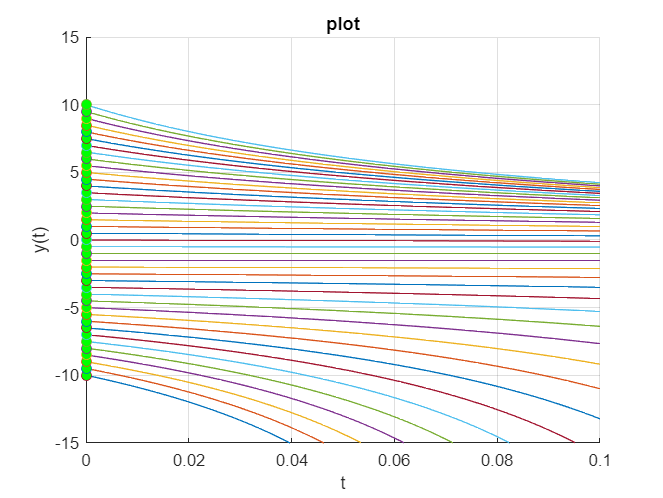

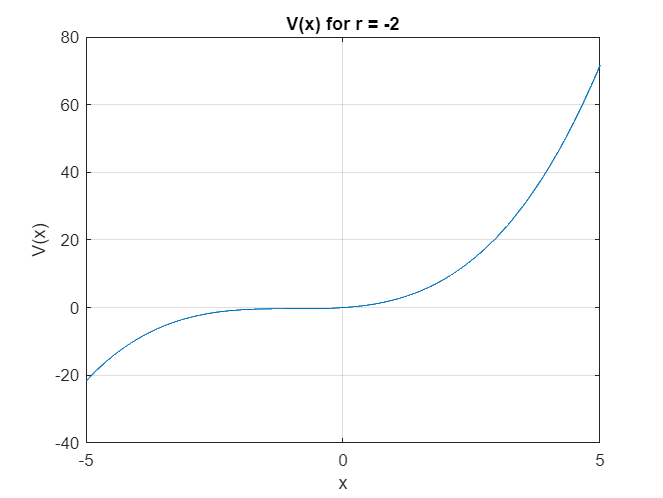

Zona 3: r = 0.00

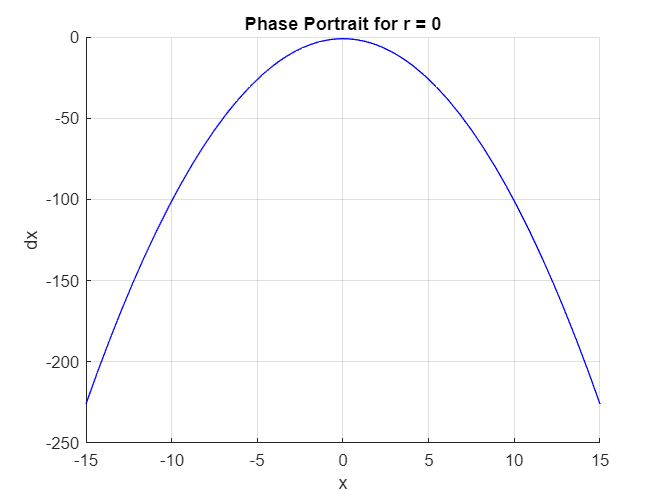

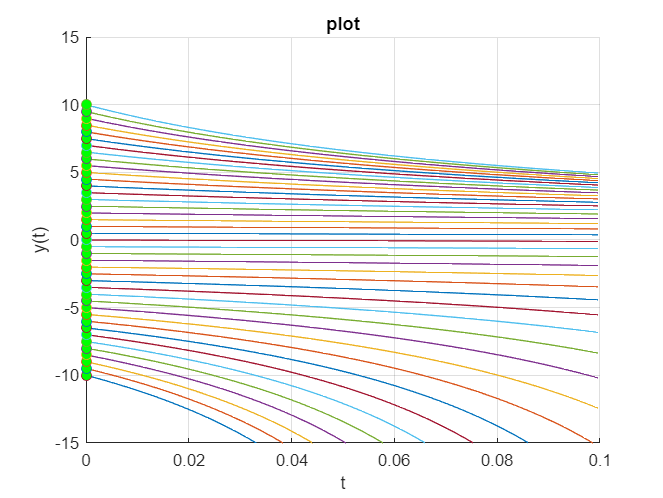

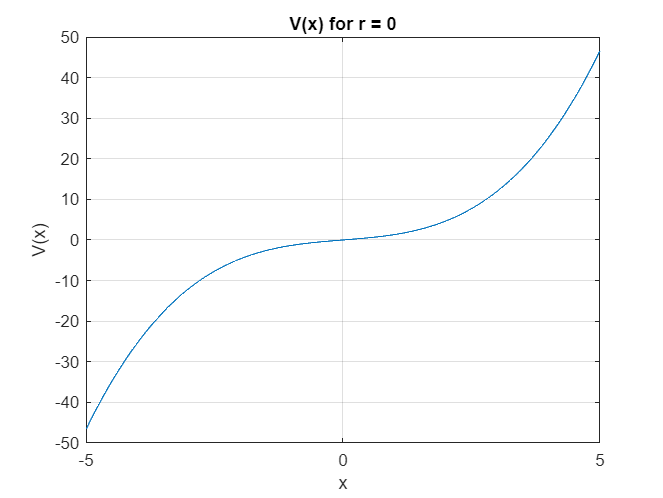

Zona 4: r = 2.00

There is a mixed Fixed Point at x = 2

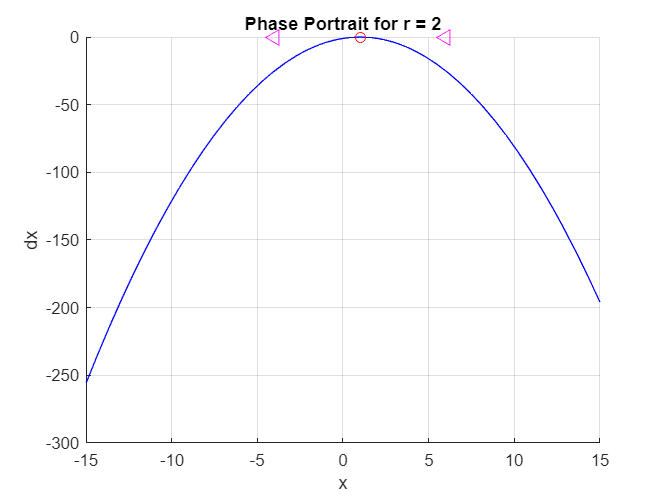

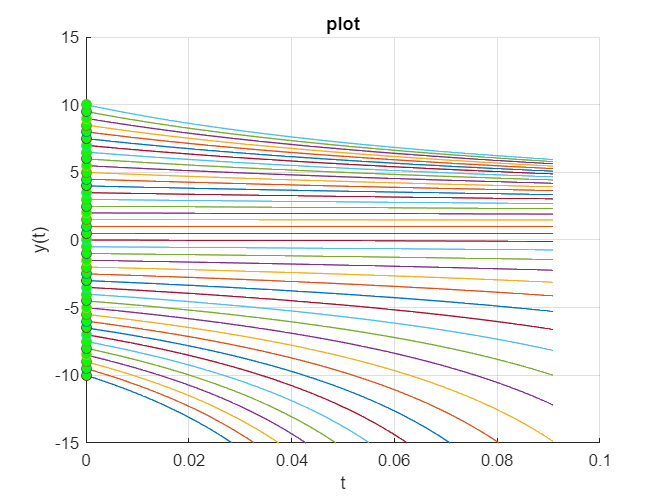

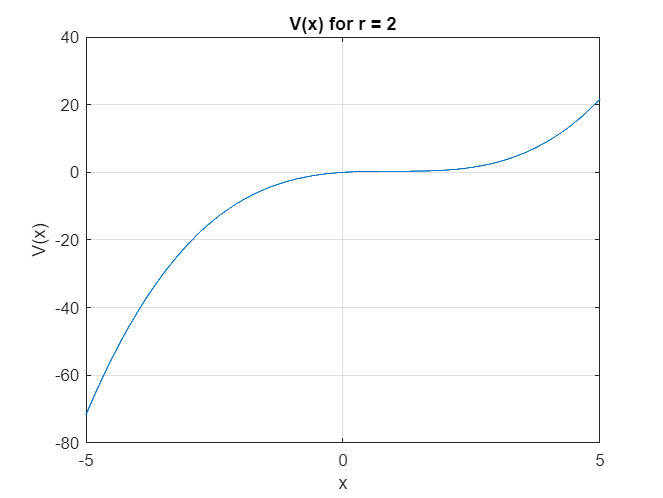

Zona 5: r = 6.00

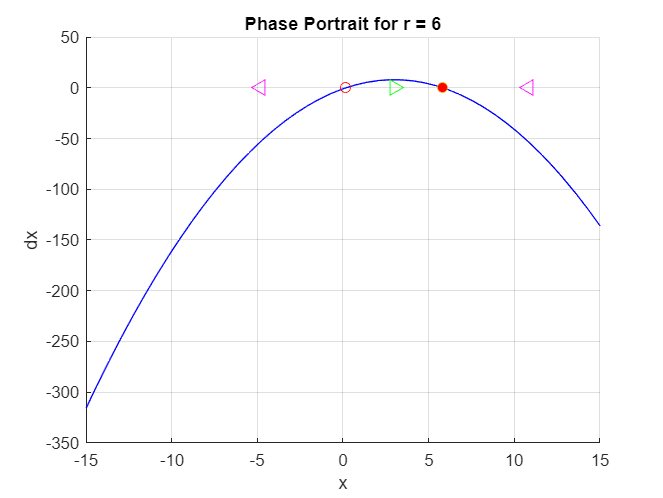

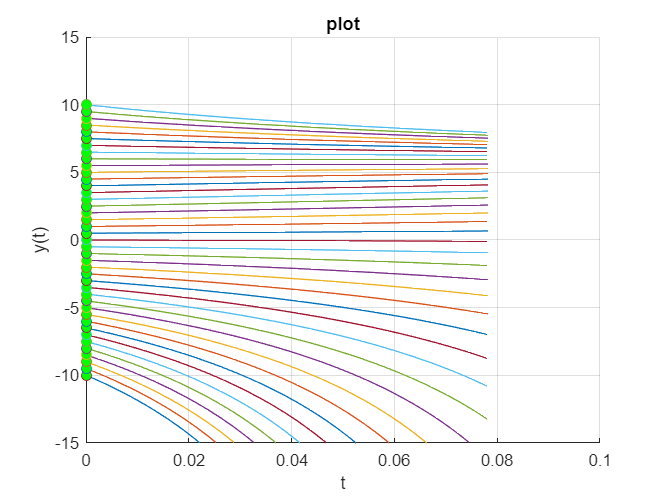

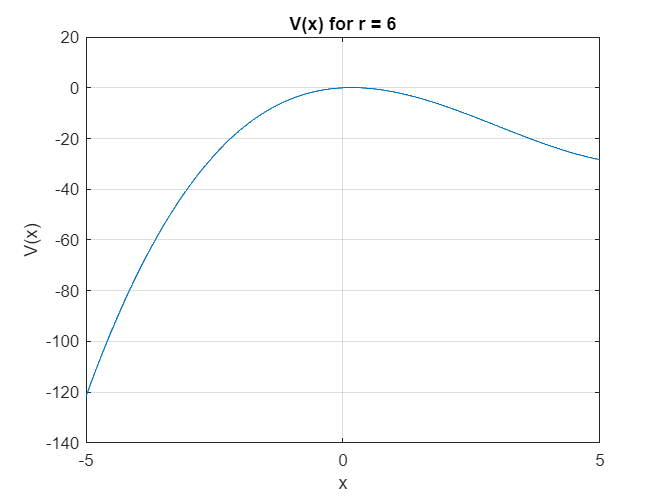

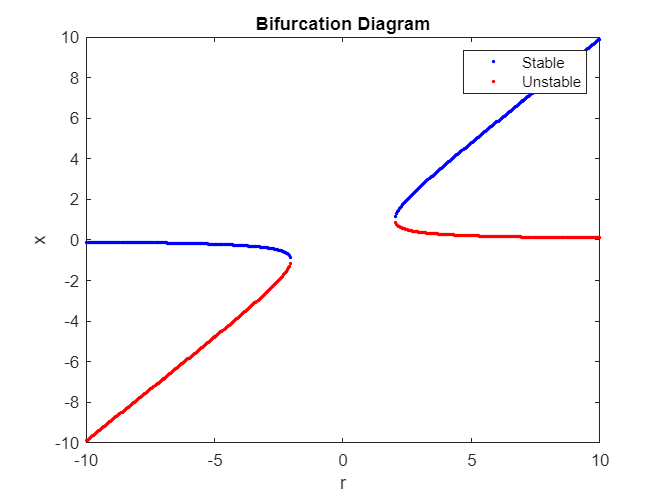

clc; clear all; close all;


syms x r
assume(x, 'real')

% Dynamic System
% Define your function here
fx1 = r*x + (x^3)/(1+x^2);
fx2 = r*x + x*exp(x);
fx3 = -1 + r*x - x^2;
fx4 = r + x - log(1+x);
fx5 = x - r*(x)/(1+x^2);
fx6 = r - x + x*exp(-x);
fx7 = x*(1-4*x)+r*x/(1+x);
fx8 = -x*(x^2-2*x-r);

% Compute the derivative once
df = diff(fx3, x);

% Convert symbolic functions to anonymous functions for faster evaluation
fx = matlabFunction(fx3, 'Vars', [r, x]);
df = matlabFunction(df, 'Vars', [r, x]);

% Compute the fixed points with respect to the control parameter 'r'
display('Possible Fixed Points:')
Fpts = solve(fx, x)

% Determine the number of fixed points
possible_n_fpts = length(Fpts);
display(['Maximum number of possible Fixed Points:', num2str(possible_n_fpts)])

eps = 1e-3;

% Lists for number of fixed points
prev_n_fpts = -5;
n_fpts = [];
% List for r values when a bifurcation occur (nº of FP change)
r_values = [];
% List for Stable and Unstable FP
stable_x_values = [];
unstable_x_values = [];
% List for values of r, for Stable and Unstable FP
r_stable = [];
r_unstable = [];

% Loop over all r values
rV = linspace(-10, 10, 500);
rV_int = -10:1:10;
rValues = sort(unique([rV, rV_int]));
for r_trial = rValues
    
    Fpts_sub = PossibleFixedPoints(Fpts, r_trial, r);
    
    % Calculate the number of Fixed Points
    n_fpts_r = length(Fpts_sub);

    % If the number of fixed points has changed, add the corresponding r value
    if n_fpts_r ~= prev_n_fpts
        r_values = [r_values, r_trial];
        n_fpts = [n_fpts, n_fpts_r];
        % Update the previous number of fixed points for the next iteration
        prev_n_fpts = n_fpts_r;
    end

    % Calculate the derivative at Fixed Points
    dfx_Fpts = df(r_trial, Fpts_sub);
   
    stb_pts = Fpts_sub(dfx_Fpts < 0);
    nstb_pts = Fpts_sub(dfx_Fpts > 0);
    for k=1:length(stb_pts)
        stable_x_values = [stable_x_values, stb_pts(k)];
    end
    for k=1:length(nstb_pts)
        unstable_x_values = [unstable_x_values, nstb_pts(k)];
    end
    % Esta es la forma de appending values to the list
    r_stable = [r_stable, r_trial*ones(1, length(stb_pts))];
    r_unstable = [r_unstable, r_trial*ones(1, length(nstb_pts))];
end

% Mostrar las zonas de bifurcación y el número de puntos fijos en cada zona
% r_values -> bifurcation points

% rValues -> trial r values
% n_fpts -> nº of FP for each zone

% z_r_trial -> representative values of each zone and bifurcation points
z_r_trial = r_zones(r_values, rValues, n_fpts);
for k = 1:length(z_r_trial)
    fprintf('Zona %d: r = %.2f', k, z_r_trial(k));
    PhasePortrait(fx, Fpts, z_r_trial(k), r, x)
    Potential(fx, z_r_trial(k), r, x)
end

% Plot bifurcation diagram
figure('Name', 'Bifurcation Diagram', 'NumberTitle', 'off');
plot(r_stable, stable_x_values, 'b.', 'DisplayName', 'Stable');
hold on;
plot(r_unstable, unstable_x_values, 'r.', 'DisplayName', 'Unstable');
title('Bifurcation Diagram');
xlabel('r');
ylabel('x');
legend;
hold off;